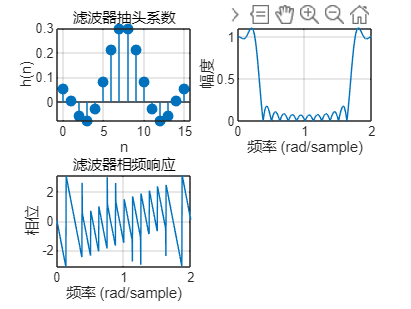

clear;clc;
N = 16; % 系数长度
n = 0:N-1; % 时间序列
H = zeros(1, N); % 初始化频域响应
H(1) = 1; 
H(2) = exp(-1i*pi*(N-1)/N);
H(3) = exp(-1i*2*pi*(N-1)/N);
H(15) = -exp(-1i*14*pi*(N-1)/N); 
H(16) = -exp(-1i*15*pi*(N-1)/N); 
h = ifft(H,N); % 求解滤波器抽头系数
[HH,w]=freqz(h,1,512,'whole');
% 绘制滤波器抽头系数图像
subplot(2,2,1);
stem(n,real(h),'filled');
grid on;
title('滤波器抽头系数');
xlabel('n');
ylabel('h(n)');
% 绘制幅频响应图像
subplot(2,2,2);
plot(w/pi, abs(HH));
grid on;
title('滤波器幅频响应');
xlabel('频率 (rad/sample)');
ylabel('幅度');
% 绘制相频响应图像
subplot(2,2,3);
plot(w/pi, angle(HH));
grid on;
title('滤波器相频响应');
xlabel('频率 (rad/sample)');
ylabel('相位');